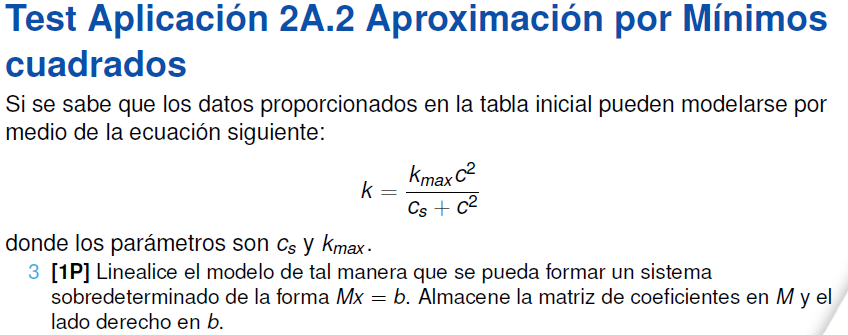

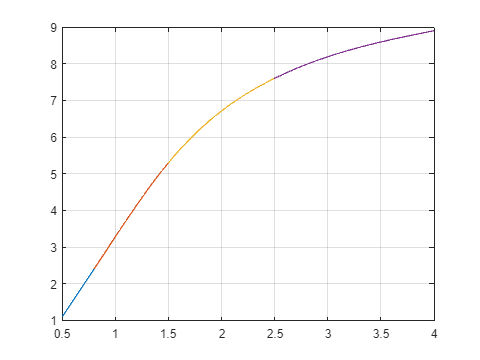

k = [1.1 2.4 5.3 7.6 8.9];
c = [0.5 0.8 1.5 2.5 4];
k_c = splinenatural(c,k);


k = [1.1 2.4 5.3 7.6 8.9]';
c = [0.5 0.8 1.5 2.5 4]';
M = [c.^2 -1*k]

M =     0.2500   -1.1000
    0.6400   -2.4000
    2.2500   -5.3000
    6.2500   -7.6000
   16.0000   -8.9000


b = (k).*(c.^2)

b =     0.2750
    1.5360
   11.9250
   47.5000
  142.4000


% formulación de ecuaciones
sol_ec = inv(M'*M)*M'*b

sol_ec =    10.0102
    1.9932



% Factorización QR
[Q,R] = gs_c(M);
b = Q'*b;
sol_gs = sustireg(R,b)

sol_gs =    10.0102
    1.9932



vdif = [abs(sol_gs - sol_ec)]'

vdif = 1.0e-14 *

    0.1776    0.1554


k_max = sol_gs(1)

k_max = 10.0102

c_s = sol_gs(2)

c_s = 1.9932


k = @(c)((k_max * c * c)/(c_s + c * c))

k = function_handle with value:
    @(c)((k_max*c*c)/(c_s+c*c))



k5_gs = k(2.6)

k5_gs = 7.7308

k6_gs = k(3)

k6_gs = 8.1952


k5 = k_c(4,1)*((2.6 - 2.5)^3) + k_c(4,2)*((2.6 - 2.5)^2) + k_c(4,3)*(2.6 - 2.5) + k_c(4,4)

k5 = 7.7370

k6 = k_c(4,1)*((3 - 2.5)^3) + k_c(4,2)*((3 - 2.5)^2) + k_c(4,3)*(3 - 2.5) + k_c(4,4)

k6 = 8.1882


vdif2 = [abs(k5 - k5_gs) abs(k6 - k6_gs)]

vdif2 =     0.0062    0.0070


function [Q, R] = gs_c(A)
    [m,n]=size(A);
    Q=zeros(m,n);
    R=zeros(n);
    for j=1:n
        R(1:j-1,j)=Q(:,1:j-1)'*A(:,j);
        temp=A(:,j)-Q(:,1:j-1)*R(1:j-1,j);
        R(j,j)=norm(temp);
        Q(:,j)=temp/R(j,j);
    end
end

function [x]=sustireg(Ea,b)
    U = triu(Ea);
    % U: Matriz triangular superior
    [~,n] = size(U);
    x = zeros(n,1);
    for k=n:-1:1
        x(k)=(b(k)- U(k,k+1:n)*x(k+1:n))/U(k,k);
    end
end

function S = splinenatural(X,Y)
    N = length(X)-1;
    H = diff(X);
    E = diff(Y)./H;
    diagprinc = 2*(H(1:N-1)+H(2:N));
    diagsupinf = H(2:N-1);
    g0 = 0; 
    gn = 0;
    A = diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
    b = 6*diff(E');
    g = A\b;
    g = [g0 g' gn];

    for i = 1:N
        S(i,1) = (g(i+1)-g(i))/(6*H(i));
        S(i,2) = g(i)/2;
        S(i,3) = E(i)-H(i)*(g(i+1)+2*g(i))/6;
        S(i,4) = Y(i);
        xx = linspace(X(i),X(i+1),100);
        yy = S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
        plot(xx,yy)
        hold on
    end
    grid on
    hold off
end